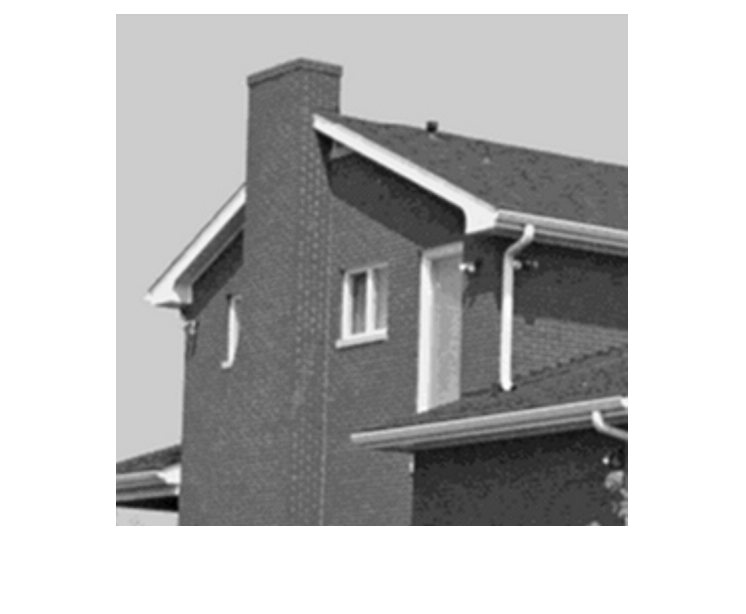

img = imread("../images/house.tif");
imshow(img)

[M, N] = size(img);

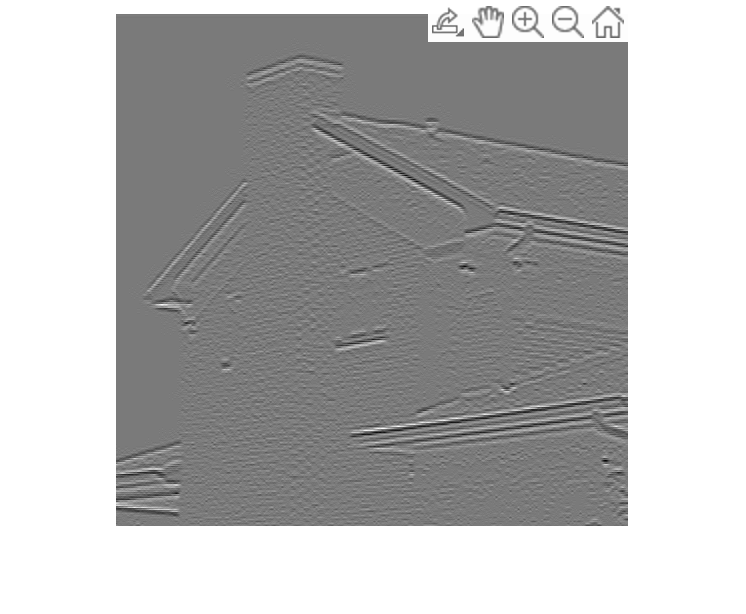

pad_img_x = padarray(img, [1, 0], "symmetric", "both");
pad_img_y = padarray(img, [0, 1], "symmetric", "both");
laplacian_kernel = [1; -2; 1];
laplacian_res_x = zeros(M, N);
laplacian_res_y = zeros(M, N);
% convolution between img and kernel
for i = 1:M
    for j = 1:N
        laplacian_res_x(i, j) = sum(sum(double(pad_img_x(i:i+2, j)) .* laplacian_kernel));
        laplacian_res_y(i, j) = sum(sum(double(pad_img_y(i, j:j+2)) .* laplacian_kernel'));
    end
end
% adjust intensity interval for visualization purposes
laplacian_res_x = laplacian_res_x - min(min(laplacian_res_x));
laplacian_res_x = laplacian_res_x / max(max(laplacian_res_x)) * 255;
imshow(uint8(laplacian_res_x))

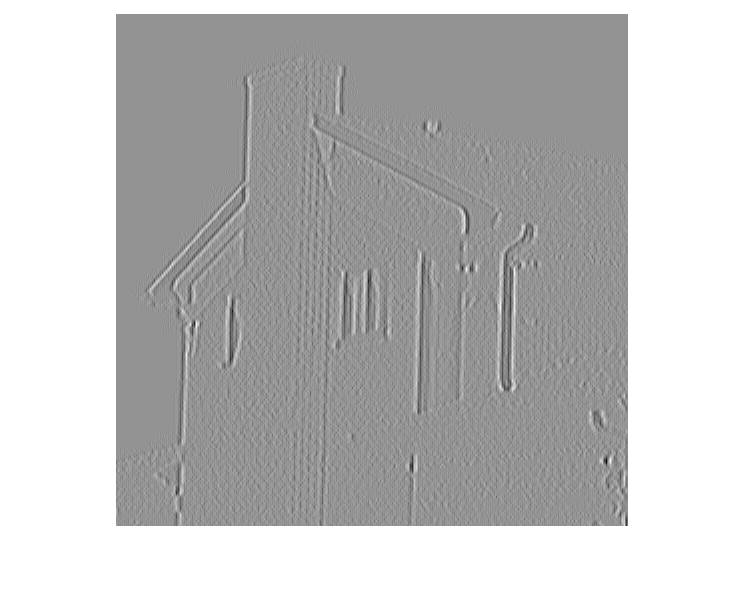

laplacian_res_y = laplacian_res_y - min(min(laplacian_res_y));
laplacian_res_y = laplacian_res_y / max(max(laplacian_res_y)) * 255;
imshow(uint8(laplacian_res_y))

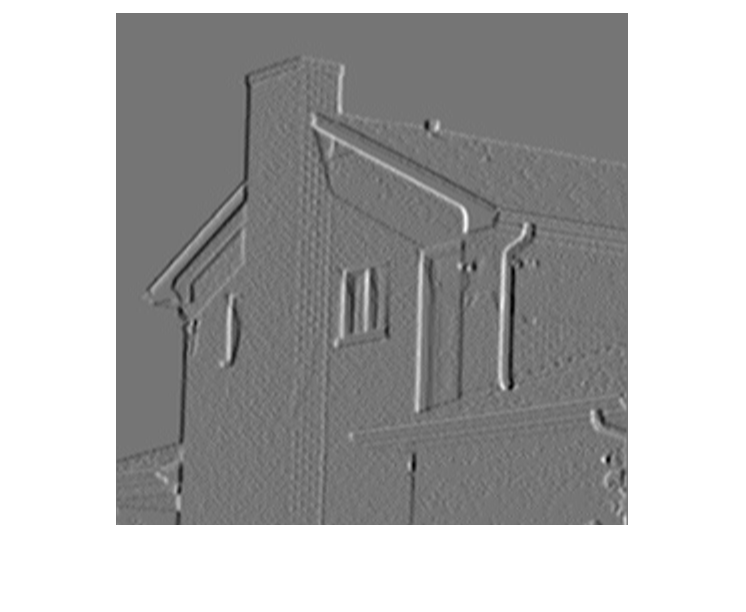

pad_img = padarray(img, [1, 1], "symmetric", "both");
sobel_kernel = [-1 -2 -1;
                   0  0  0;
                   1  2  1];
sobel_res_x = zeros(M, N);
sobel_res_y = zeros(M, N);
% convolution between img and sobel kernels
for i = 1:M
    for j = 1:N
        sobel_res_x(i, j) = sum(sum(double(pad_img(i:i+2, j:j+2)) .* sobel_kernel'));
        sobel_res_y(i, j) = sum(sum(double(pad_img(i:i+2, j:j+2)) .* sobel_kernel));
    end
end
% adjust intensity interval for visualization purposes.
sobel_res_x = sobel_res_x - min(min(sobel_res_x));
sobel_res_x = sobel_res_x / max(max(sobel_res_x)) * 255;
imshow(uint8(sobel_res_x))

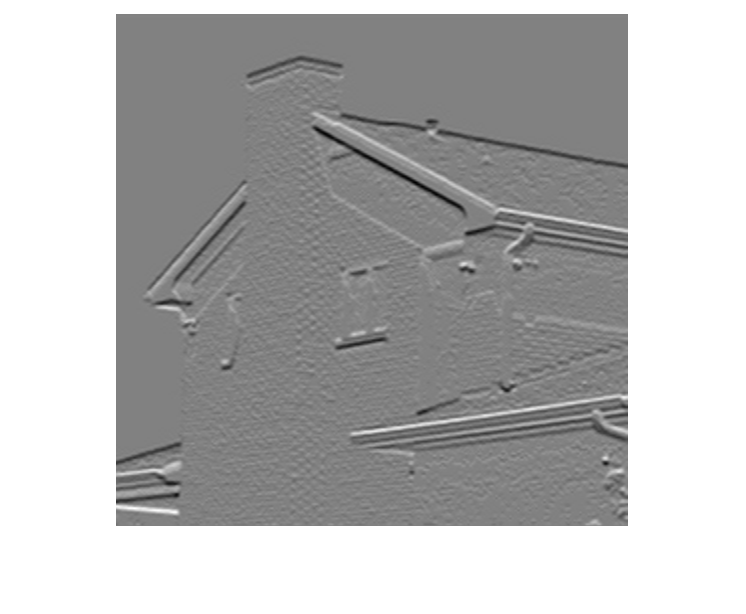

sobel_res_y = sobel_res_y - min(min(sobel_res_y));
sobel_res_y = sobel_res_y / max(max(sobel_res_y)) * 255;
imshow(uint8(sobel_res_y))